clear
Freqs = CleanDir('C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq');

Deci.Analysis.Freq.Extra.Corr.Behavior = {'NegPun2N4Q\mEV' 'NegPun2N4Q\mPE' 'NegPun2N4Q\mR' 'NegPun2N4Q\mnPE' 'NegPun2N4Q\mnEV' 'NegPun2N4Q\mEVC' ...
                                          'NegPun2N4Q\sEV' 'NegPun2N4Q\sPE' 'NegPun2N4Q\sR' 'NegPun2N4Q\snPE' 'NegPun2N4Q\snEV' 'NegPun2N4Q\sEVC'};
Deci.Analysis.Freq.Extra.Corr.categorical = [7:12];
Deci.Analysis.Freq.Extra.Corr.signed = [7:12];

%x + x4*x9 + x3*x8 x1*x6 + + x3*x8-x8 + x1*x6
states = [20 21 23 24 120 121];

for subj = 1:length(Freqs)

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq_2\' Freqs{subj} '\Fdb Onset\All\FCz.mat']);

    data{subj} = cat(1,rawfreq.trialpow{:});

    load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\RawFreq\' Freqs{subj} '\Stim Onset\All\FCz.mat']);

    bsl{subj} = nanmean(cat(1,rawfreq.trialpow{:}),1);

    data{subj} = [data{subj} - bsl{subj}]./bsl{subj};
    %data{subj} = [data{subj} - bsl{subj}]; %./bsl{subj};

    b = load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\NegPun2N4Q\S\' filesep Freqs{subj} '\All.mat']);


    for behv = 1:length(Deci.Analysis.Freq.Extra.Corr.Behavior)

        load(['C:\Users\John\Desktop\Instru2\ProcessedData_all_Stim_bbcorr\Analysis\Extra\' Deci.Analysis.Freq.Extra.Corr.Behavior{behv} filesep Freqs{subj} '\All.mat']);

        bparam{behv} = cat(2,param{:})';
        bparam{behv} = bparam{behv}(rawfreq.trials);
        if ismember(behv,Deci.Analysis.Freq.Extra.Corr.signed)
        bparam{behv}(bparam{behv} == -1) = 2;
        bparam{behv}(bparam{behv} == 0) = 1;
        end

        for stat = 1:length(states)

            blk = 1;
            for block = 1:length(b.param)

               

                if ismember(states(stat),b.param{block})
                   pos = ismember(b.param{block},states(stat));

                   blkparam{behv}(stat,subj,blk,:) = nan([40 1]);

                   blkparam{behv}(stat,subj,blk,:) = [param{block}(pos) nan([1 40-length(param{block}(pos))])];

                   blk = blk + 1;
                else
                    continue
                end

            end
            
        end


    end

    behav{subj} = cat(2,bparam{:});

end

brain = cat(1,data{:});
behavior = cat(1,behav{:});

BehvTitles = {'mEV' 'mPe' 'mR' 'mnPe' 'mnEV' 'mEVC'...
             'sEV' 'sPe' 'sR' 'snPe' 'snEV' 'sEVC' 'brain'};

BehvTitlesall = {'mEV' 'mPe' 'mR' 'mnPe' 'mnEV' 'mEVC'...
                 'sEV' 'sPe' 'sR' 'snPe' 'snEV' 'sEVC',...
                 'mEV:sEV' 'mPe:sPe' 'mR:sR' 'mnPe:snPe' 'mnEV:snEV' 'mEVC:sEVC'};

%Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1  + mPe*sPe  + mR*sR' + mR + sR;

Deci.Analysis.Freq.Extra.Corr.formula = 'brain ~ 1 + mnPe*snPe + mPe*sPe + mEVC*sEVC';
BBCorr = array2table([behavior brain],'VariableNames',BehvTitles);


mdl = fitlm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

mdl = Linear regression model:
    brain ~ 1 + mPe*sPe + mnPe*snPe + mEVC*sEVC

Estimated Coefficients:
                    Estimate        SE          tStat        pValue  
                   __________    _________    _________    __________

    (Intercept)       0.12572      0.03129        4.018    5.9003e-05
    mPe             0.0052879    0.0016673       3.1716     0.0015194
    mnPe            0.0089837      0.00235       3.8229    0.00013247
    mEVC            -0.011694    0.0028801      -4.0602    4.9286e-05
    sPe_2            0.060014     0.028217       2.1269      0.033448
    snPe_2            0.01876     0.032754      0.57275       0.56682
    sEVC_2          0.0099298     0.029558      0.33594       0.73692
    

%mdl2 = fitlm(BBCorr,'brain ~ 1 + mPe','CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)

% mdl2 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'PEnter',0)
% mdl3 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
% mdl4 = stepwiselm(BBCorr,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical)
% 
% mdl5 = stepwiselm(BBCorr,Deci.Analysis.Freq.Extra.Corr.formula,'CategoricalVars',Deci.Analysis.Freq.Extra.Corr.categorical,'Criterion','aic')

% 
% Deci.Analysis.Freq.Extra.Corr.Behavior = {'StableDoubleNegQ\mEV' 'StableDoubleNegQ\mPE' 'StableDoubleNegQ\mEV_next' 'StableDoubleNegQ\maEV' 'StableDoubleNegQ\mR' ...
%                                           'StableDoubleNegQ\sEV' 'StableDoubleNegQ\sPE' 'StableDoubleNegQ\sEV_next' 'StableDoubleNegQ\saEV' 'StableDoubleNegQ\sR'};

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


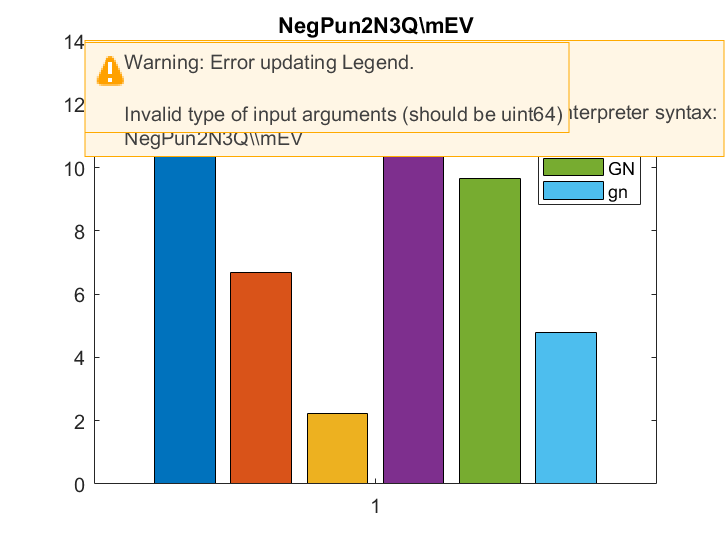

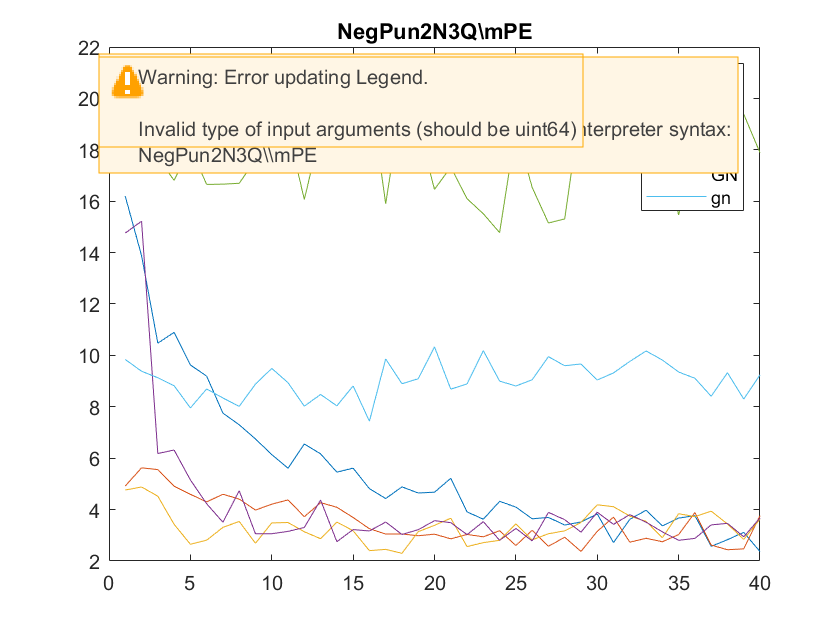

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


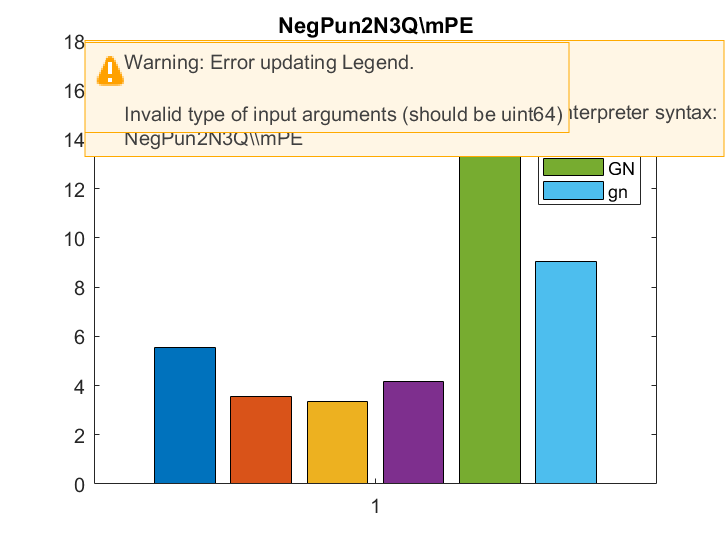

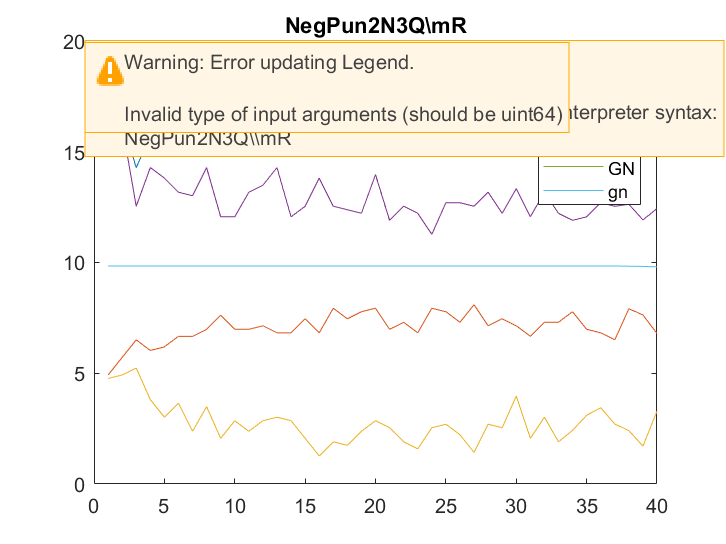

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


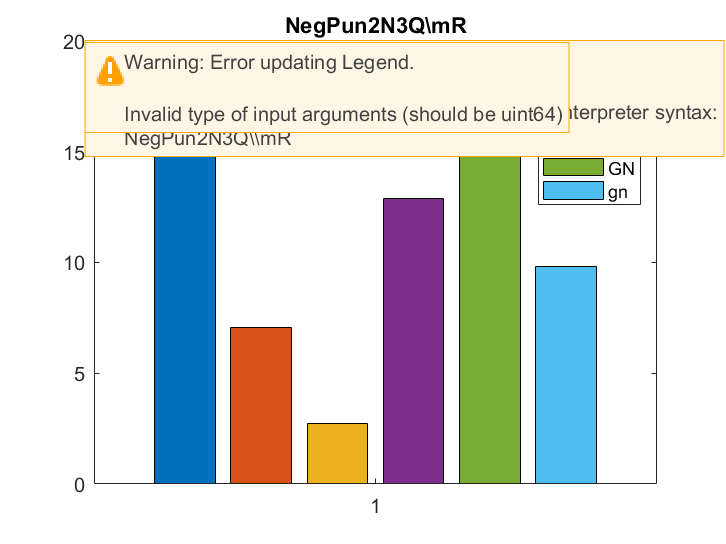

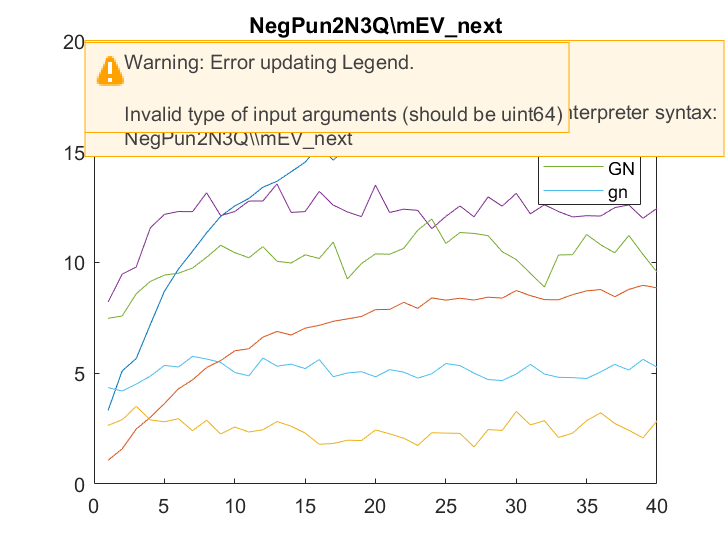

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


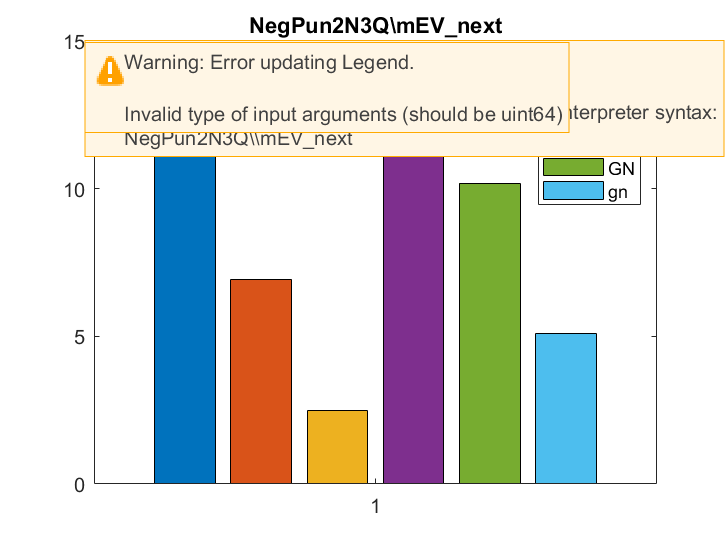

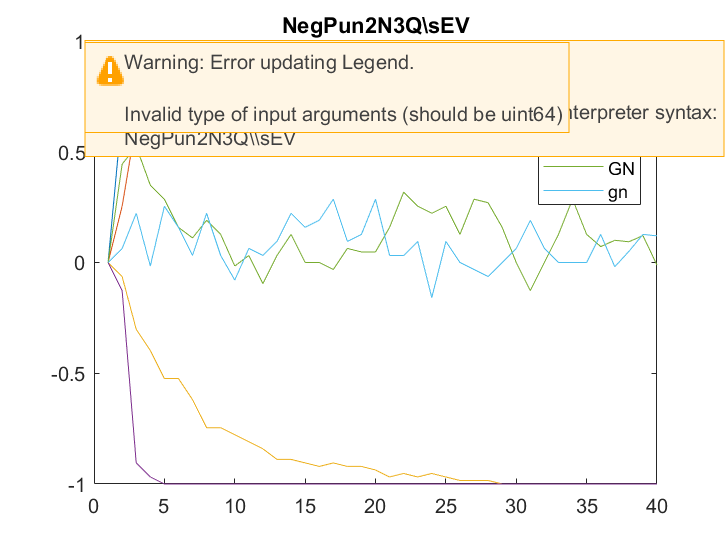

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


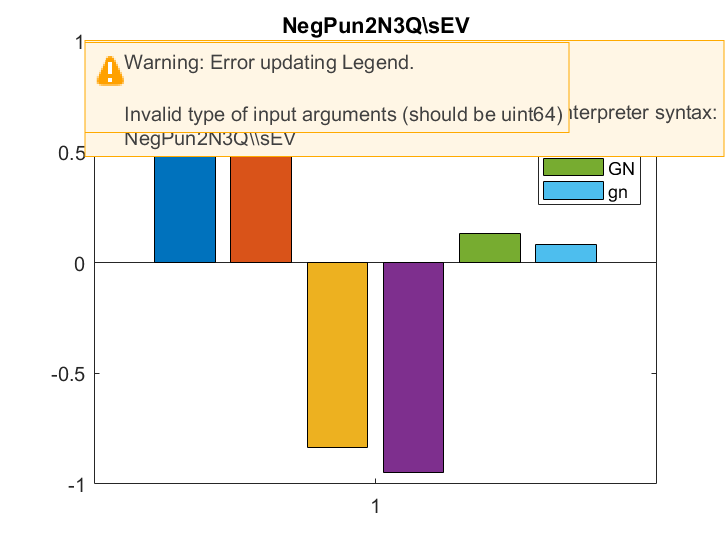

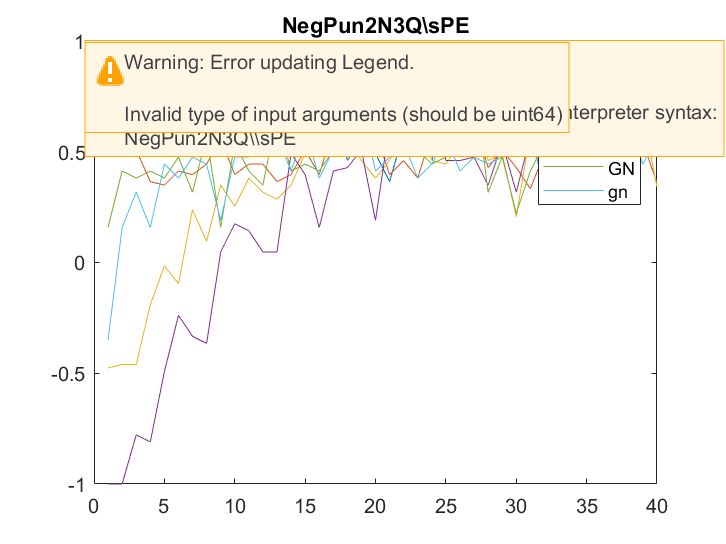

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


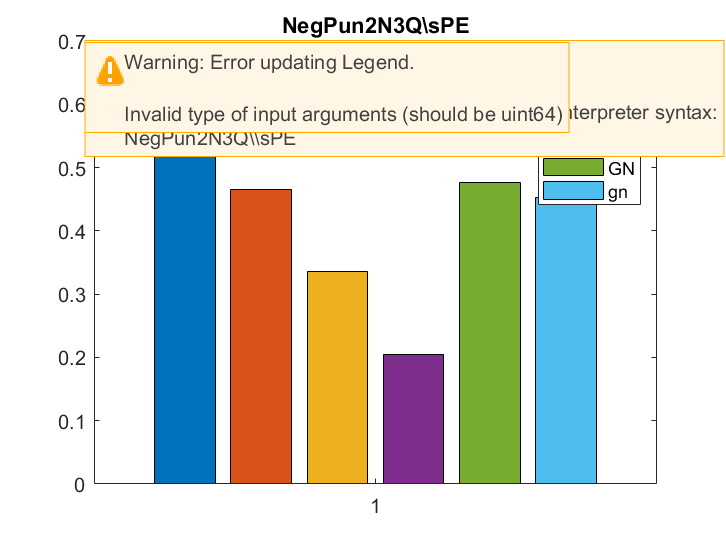

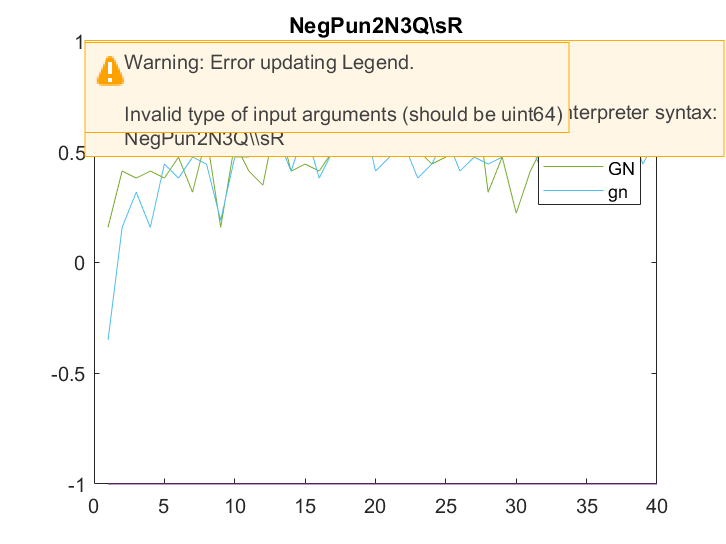

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


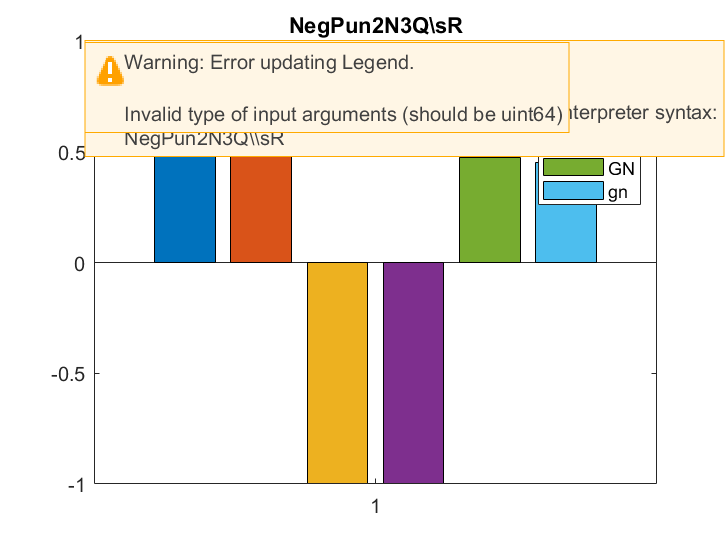

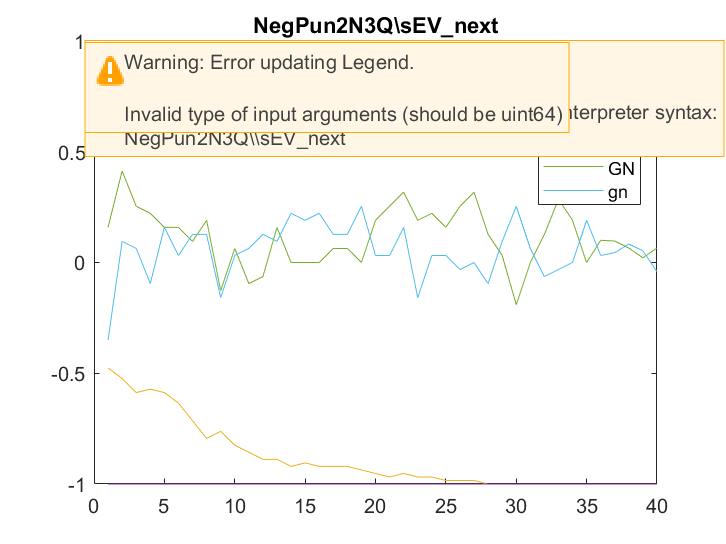

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


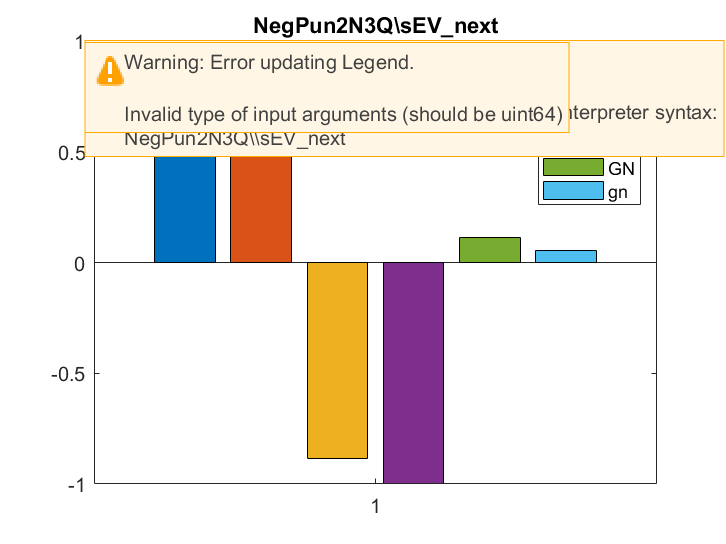

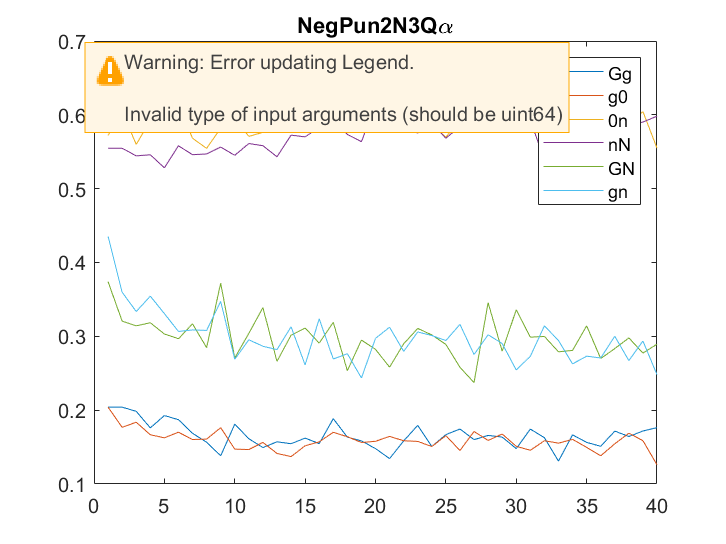

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


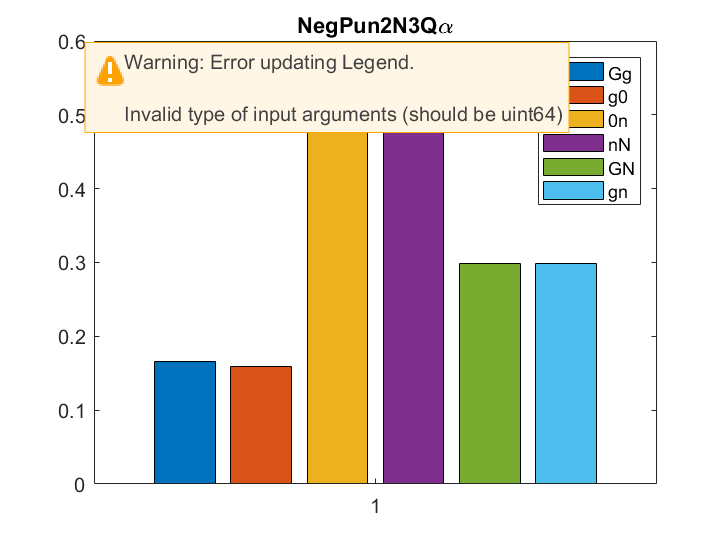


statenames = {'Gg' 'g0' '0n' 'nN' 'GN' 'gn'};
for blk = 1:length(blkparam)

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3));

    figure;
    plot(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4));
    CleanBars(dat')
    title(Deci.Analysis.Freq.Extra.Corr.Behavior{blk})
    legend(statenames)
end

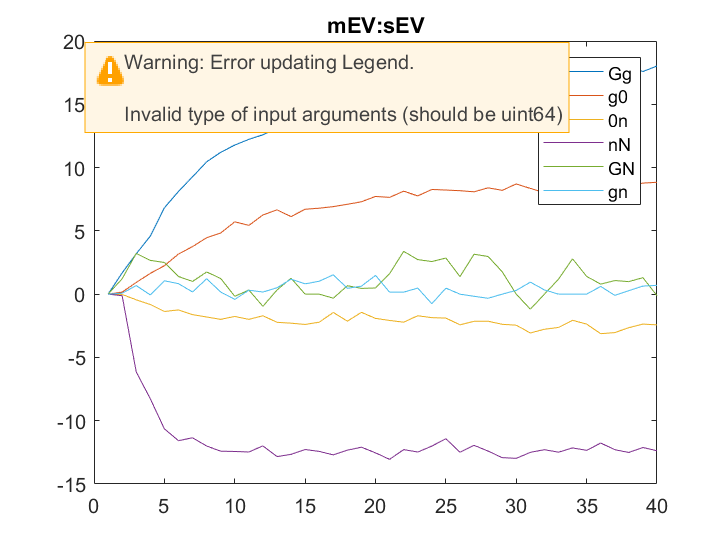

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


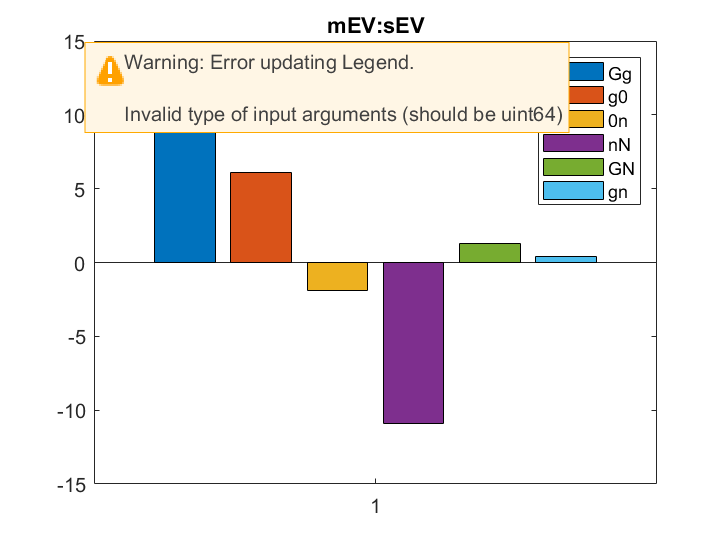

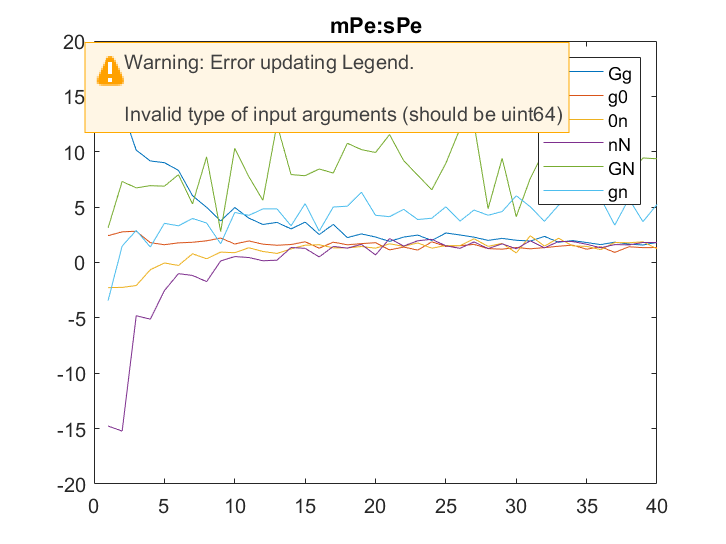

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


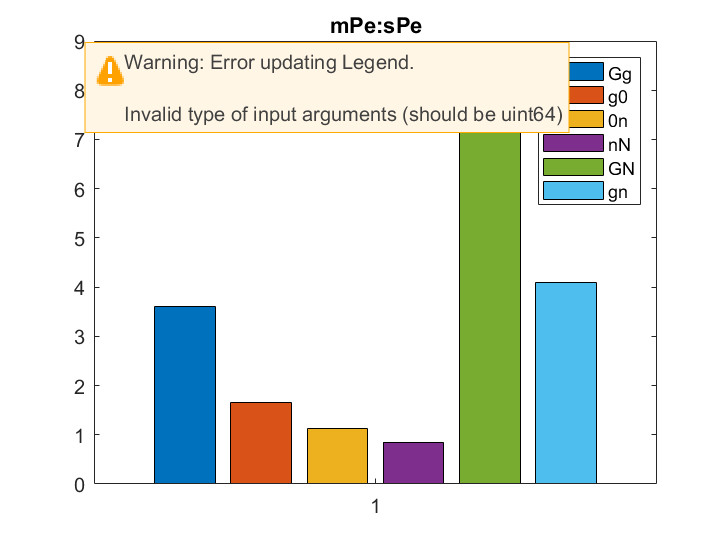

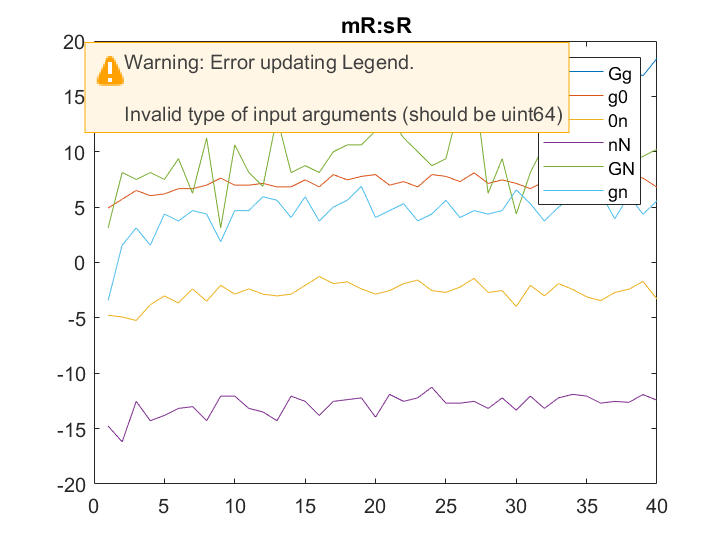

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


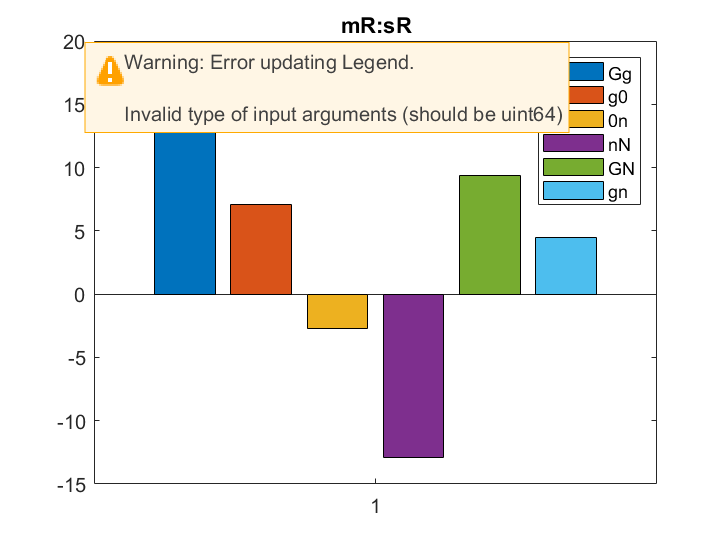

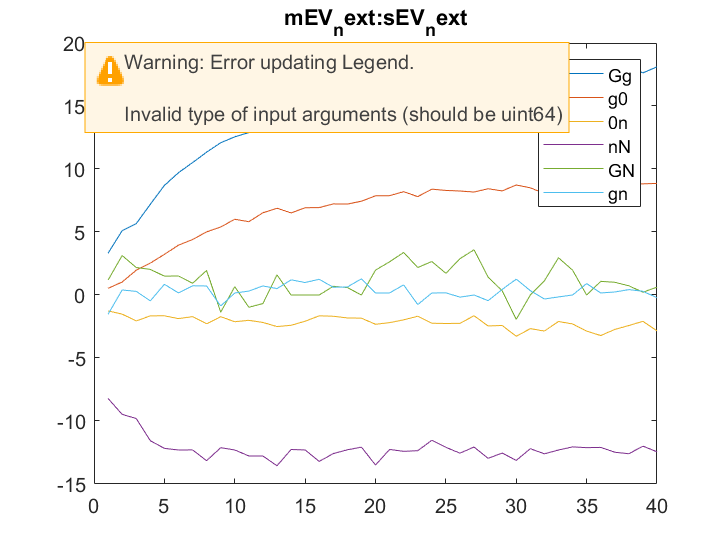

ans =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


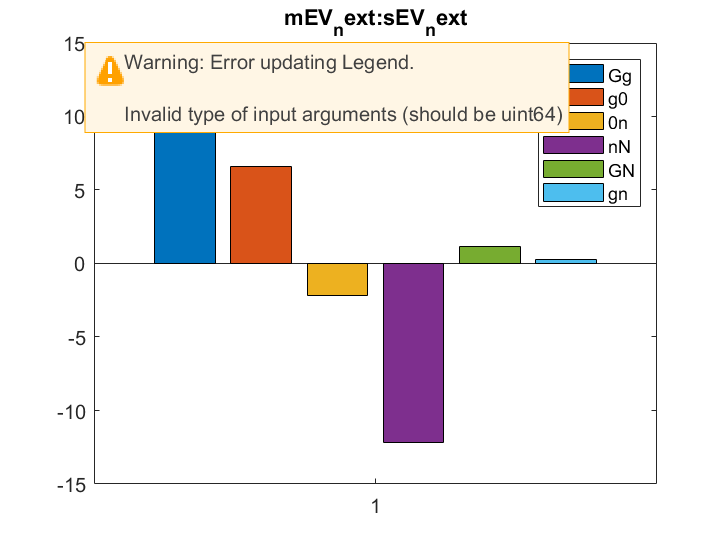


BehvTitlesInt = {'mEV:sEV' 'mPe:sPe' 'mR:sR', 'mEV_next:sEV_next'};

for blk = 1:4

    dat = squeeze(nanmean(nanmean(blkparam{blk},2),3)).*squeeze(nanmean(nanmean(blkparam{blk+4},2),3));
    figure;
    plot(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

    figure;
    dat = squeeze(nanmean(nanmean(nanmean(blkparam{blk},2),3),4)).*squeeze(nanmean(nanmean(nanmean(blkparam{blk+4},2),3),4));
    CleanBars(dat')
    title(BehvTitlesInt{blk})
    legend(statenames)

end